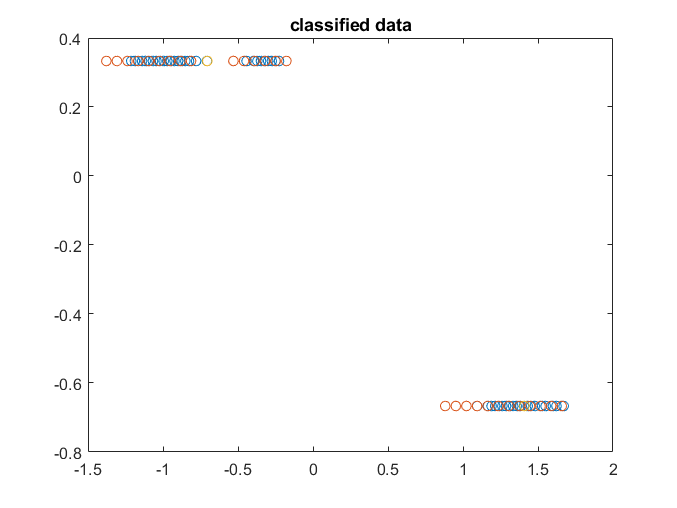

data = load('fisheriris.mat');
classA = data.meas(101:150,3:4);
classB = data.meas(1:100,3:4);
[ra,ca] = size(classA);
[rb,cb] = size(classB);
data1 = [classA;classB];
dat = [classA ones(ra,1);-classB -ones(rb,1)];
dat = zscore(dat);
[r,c] = size(data.meas(:,3:4));
w = rand(c+1,1);
iter = 100;
outer= 0;
for j =1:iter
    outer= outer+1;
    w_init = w;
    w_temp = zeros(c+1,1);
    for i=1:r
        c1 = dat(i,:)*w;
        if c1<=0
            w_temp = w_temp + dat(i,:)';
        elseif c1>0
            continue
        end 
    end
    w = w + w_temp;
    if(w == w_init)
        break;
    end 
end
A1 =dat;
subplot(2,1,1)
t3 = [zeros(ra,1);ones(rb,1)];
w3_hat = ((inv(A1'*A1))*A1')*t3;
y_ls = dat*w3_hat;
title('least squares')
plot(dat,y_ls,'o');
y = dat*w;
subplot(2,1,2)
title('batch perceptron')

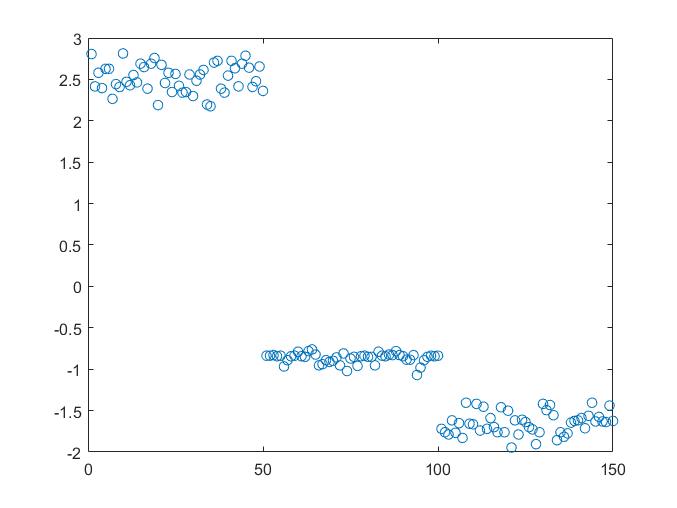

plot(y,'o')

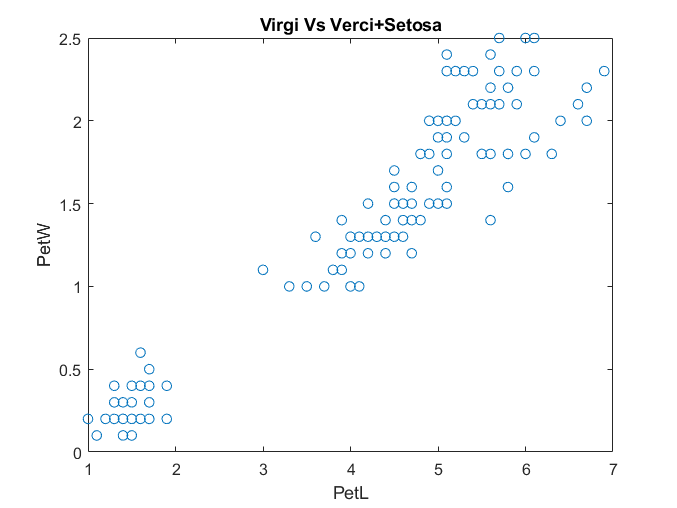


figure()
plot(data.meas(:,3),data.meas(:,4),'o')
title('Virgi Vs Verci+Setosa')
xlabel('PetL')
ylabel('PetW')